The aim of this analysis is to create a function that calculates RMS capacitor current and output voltage ripple given output capacitor size, ESR and inductor current, and average output current.

I'm following the TI app note: *TIDUES0E – JUNE 2019 – REVISED APRIL 2024  Bidirectional, Dual Active Bridge Reference Design for Level 3 Electric Vehicle Charging Stations*

Assume that the load current is dc

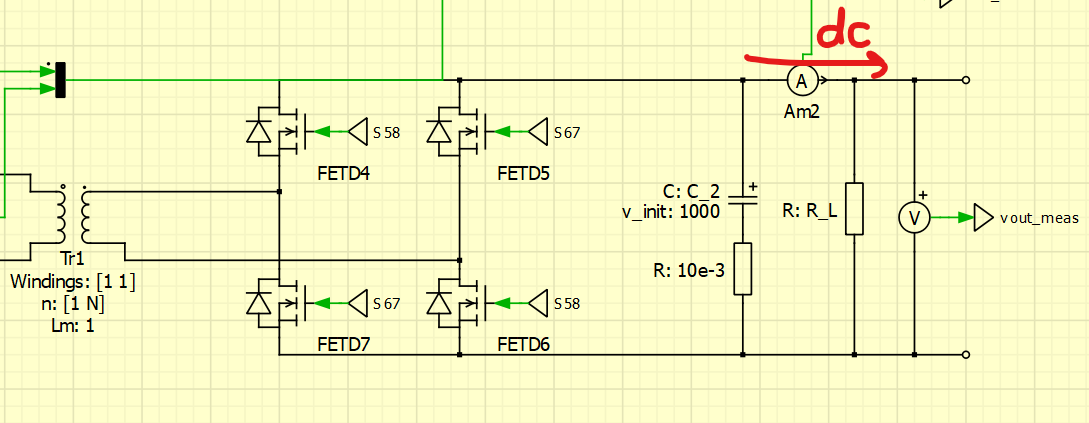


$$I_{\textrm{out}} =\frac{V_{\textrm{out}} }{R_{\textrm{load}} }$$


Using dab.plecs in this analysis, I've confirmed that the rectified secondary current indeed looks like this:

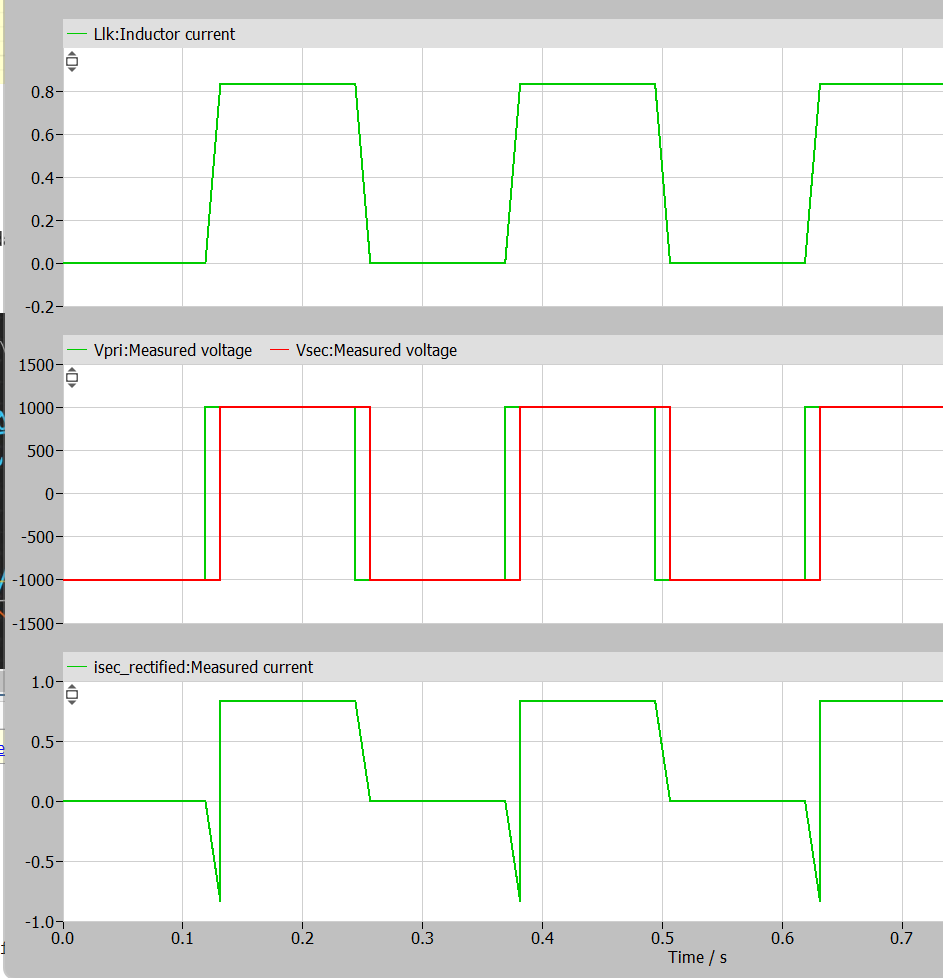

when probed here

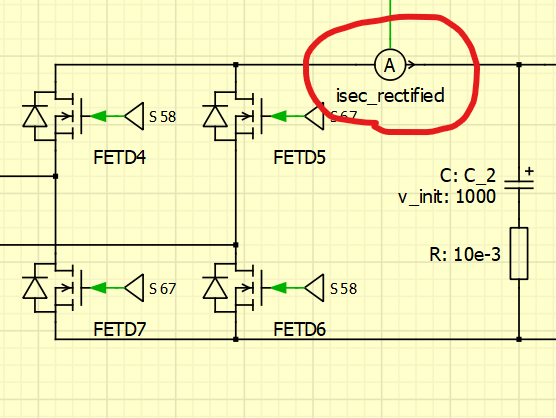

Tim McRae's video goes through the steps of calculating Cout, then concludes by saying that usually, Cout is sized according to the *load transient requirement*, **not** delta Q.

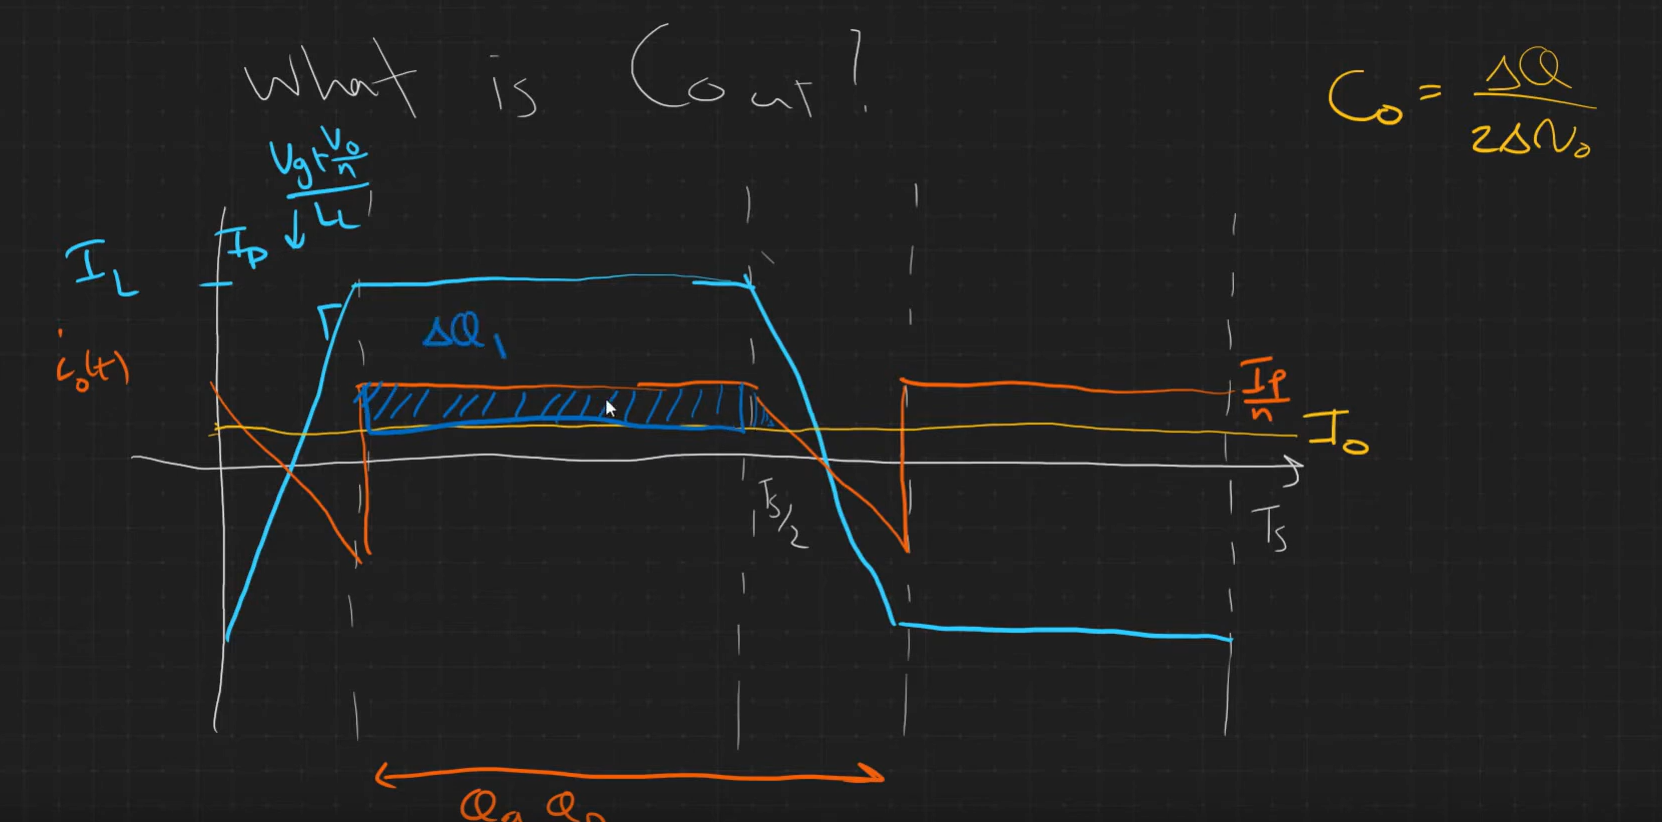

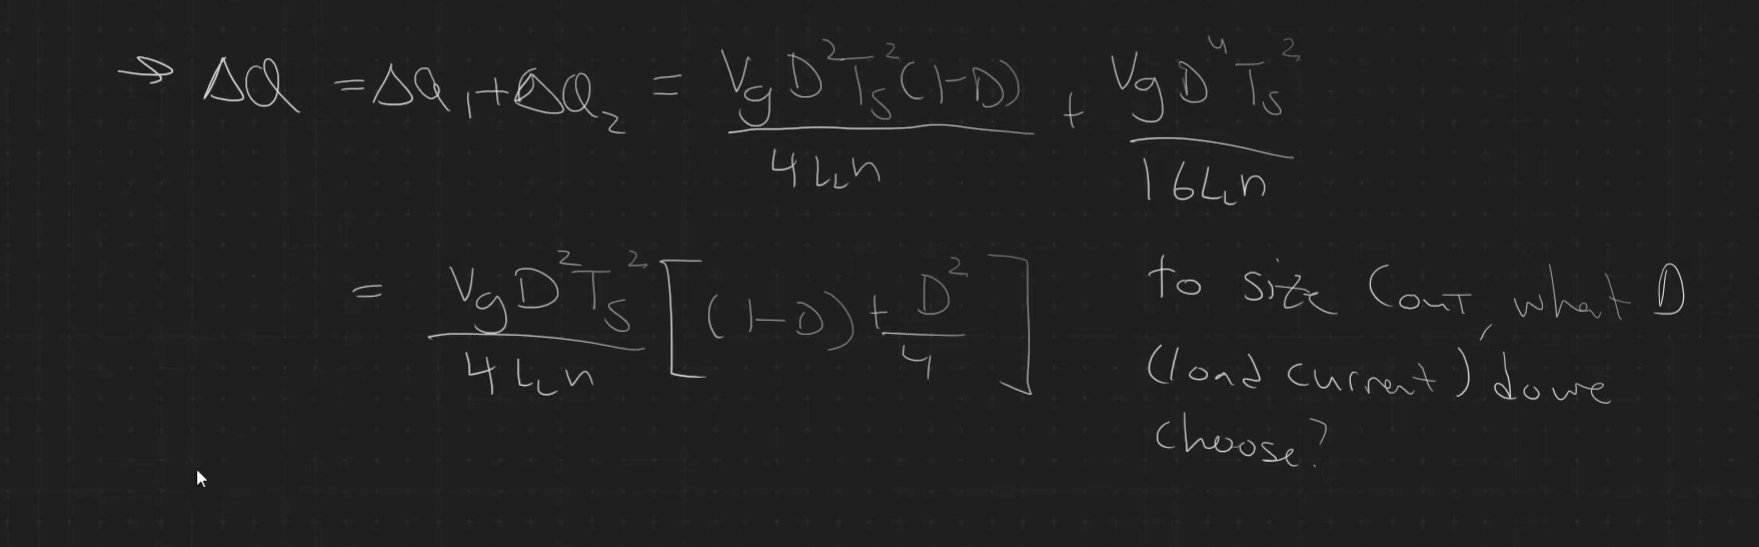

Vin = 800:100:1200;
Vg = Vin;
Phi = 0:0.1:0.4;
D = Phi;
f = 400e3;
Ts = 1/f;
L_l = 300e-6;
N = 1;
deltaQ = (Vg .* D.^2 .* Ts.^2)./(4.*L_l .* N) .* ((1-D) + D.^2 / 4);

Vout = 1000;
deltaVout = 0.01 * Vout;
Cout = deltaQ ./ (2 .* deltaVout);